# **11 Effect of non-random mixing on rubella transmission and control**

 **Overview**

In part I, you will calculate the WAIFW matrix for different assumptions about mixing patterns, using values of the age-specific force of infection for rubella for the UK. In part II, you will explore the implications of different mixing patterns on the impact of MMR vaccination on the transmission dynamics of rubella.

## **PART I: Calculating WAIFW matrices**

To describe the transmission dynamics of rubella in the UK, accounting for this age-dependency, we will use an age-structured SEIR modelwith the following structure:    

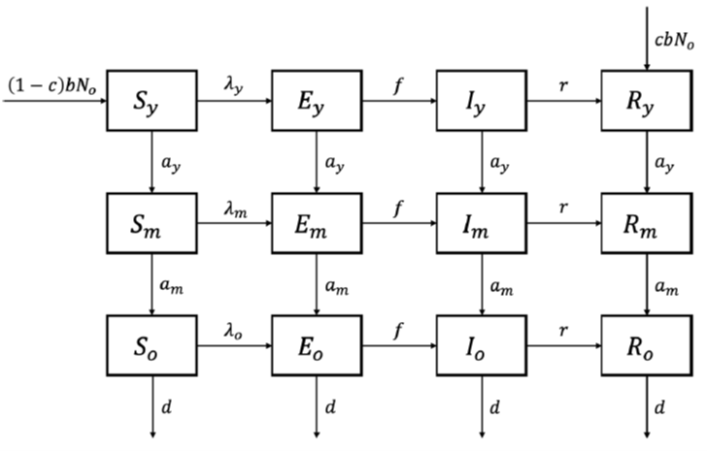                          

The population is stratified into three age classes, namely the young (0-14 years), middle-aged (15-29 years) and the old (≥30 years). Young and middle-aged individuals spend an average of 15 years in each compartment; old individuals spend an average of 30 years in the old compartment. Deaths only affect individuals in the old compartment. The total population size remains constant over time with 60,000 individuals, and 15,000, 15,000 and 30,000 young, middle-aged and old individuals respectively. Newly infected individuals typically became infectious after an average period of 10 days and stay infectious for an average of 11 days thereafter.

#### 1. Fill in the table below.

clear; clc; close all;
N0 = 60000;     
N_y = 15000;    % population size of young group 
N_m = 15000;    % population size of middle-aged group
N_o = 30000;    % population size of old group
b = 1/(60*365);   % natural birth rate
d = 1/(30*365);   % natural death rate
a_y = 1/(15*365); % rate at which young individuals age
a_m = 1/(15*365); % rate at which middle-aged individuals age
f = 1/10;       % rate at which individuals become infectious
r = 1/11;       % rate at which infectious individuals recover

#### 2. The number of infectious individuals can be calculated using the expression: force of infection*number of individuals who are susceptible*average duration of infectiousness Complete the following table to calculate the number of infectious individuals in each age category for the population in the mode.

lambda_y = 0.000364;
lambda_m = 0.000114;
lambda_o = 0.000114;
S_y0 = 5012;
S_m0 = 3083;
S_o0 = 2739;

I_y0 = lambda_y * S_y0 / r;
I_m0 = lambda_m * S_m0 / r;
I_o0 = lambda_o * S_o0 / r;

fprintf('Number of Infectioous\n▶ Young : %.1f\n▶ Middle-aged : %.1f\n▶ Old : %.1f\n',I_y0,I_m0,I_o0)

Number of Infectioous
▶ Young : 20.1
▶ Middle-aged : 3.9
▶ Old : 3.4


*The number of susceptible individuals in each age category have been calculated using the expressions in the Appendix.

#### 3. Write down the expressions for the force of infection (FOI) λi for each group (young, middled-aged, and old) in terms of βij and Ij, where βij is the rate at which a specific susceptible individual in ith group and an infectious individual in jth group come into effective contact per unit time.

 
$${\left[\begin{array}{ccc}
\beta_{yy}  & \beta_{ym}  & \beta_{yo} \\
\beta_{my}  & \beta_{mm}  & \beta_{mo} \\
\beta_{oy}  & \beta_{om}  & \beta_{oo} 
\end{array}\right]}{\left[\begin{array}{c}
I_y \left(t\right)\\
I_m \left(t\right)\\
I_o \left(t\right)
\end{array}\right]}={\left[\begin{array}{c}
\lambda_y \left(t\right)\\
\lambda_m \left(t\right)\\
\lambda_o \left(t\right)
\end{array}\right]}$$


#### 4. Calculate appropriate contact parameters βij for the following WAIFW matrix A and B:

 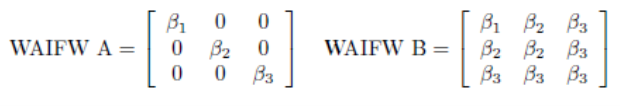

WAIFW_A = zeros(3,3);

Abeta1 = lambda_y / I_y0;
Abeta2 = lambda_m / I_m0;
Abeta3 = lambda_o / I_o0;

WAIFW_A(1,1) = Abeta1;
WAIFW_A(2,2) = Abeta2;
WAIFW_A(3,3) = Abeta3;

WAIFW_B = zeros(3,3);

Bbeta3 = lambda_o / (I_y0+I_m0+I_o0);
Bbeta2 = (lambda_m - I_o0 * Bbeta3) / (I_y0+I_m0);
Bbeta1 = (lambda_y - I_m0 * Bbeta2 - I_o0 * Bbeta3) / I_y0;

WAIFW_B(1:3,1:3) = Bbeta3;
WAIFW_B(1:2,1:2) = Bbeta2;
WAIFW_B(1,1) = Bbeta1;

beta = 1.0530e-05;
%beta = (Abeta1+Abeta2+Abeta3+Bbeta1+Bbeta2+Bbeta3)/6;  %아직도 의문,,,
WAIFW_H = beta*ones(3,3);

fprintf(['WAIFW A : beta_1 = %f , beta_2 = %f , beta_3 = %f\n' ...
    'WAIFW B : beta_1 = %f , beta_2 = %f , beta_3 = %f\n'], ...
    Abeta1,Abeta2,Abeta3,Bbeta1,Bbeta2,Bbeta3)

WAIFW A : beta_1 = 0.000018 , beta_2 = 0.000029 , beta_3 = 0.000033
WAIFW B : beta_1 = 0.000017 , beta_2 = 0.000004 , beta_3 = 0.000004


#### 5. Which WAIFW structure (A or B) is the most realistic in a given population? 

WAIFW B is more realistic since WAIFW A assumes there is no contact between different age groups.

#### 6. In which of the following populations should it be easiest to control rubella transmission using childhood MMR vaccination and why?

#### i) a population with mixing patterns described by WAIFW A

#### ii) a population with mixing patterns described by WAIFW B?

WAIFW B

Since there is no transmission between different age group in WAIFW A, it is hard to control rubella transmission in old age group using childhood MMR vaccination.

## **PART II: The implications of heterogeneous mixing**

E_y0 = 0;R_y0 = N_y-S_y0-I_y0;
E_m0 = 0;R_m0 = N_m-S_m0-I_m0;
E_o0 = 0;R_o0 = N_o-S_o0-I_o0;  % S랑 I는 2번 정답에서 나온거 이용

initial_value = [S_y0;E_y0;I_y0;R_y0;...
                 S_m0;E_m0;I_m0;R_m0;...
                 S_o0;E_o0;I_o0;R_o0];

% Differential Method
t_stamp = 1:200*365;
[~,y_H] = ode45(@(t,y) ODEftn(WAIFW_H,0,y,t), t_stamp , initial_value);
[~,y_A] = ode45(@(t,y) ODEftn(WAIFW_A,0,y,t), t_stamp , initial_value);
[~,y_B] = ode45(@(t,y) ODEftn(WAIFW_B,0,y,t), t_stamp , initial_value);
[~,y_A_vac] = ode45(@(t,y) ODEftn(WAIFW_A, 0.86,y,t), t_stamp , initial_value);
[~,y_B_vac] = ode45(@(t,y) ODEftn(WAIFW_B, 0.86,y,t), t_stamp , initial_value);

#### 1.Compare the long-term age-specific values for the proportion of individuals who are susceptible and the daily number of new infections per 100,000 computed with and without incorporating WAIFW. Is this what you would expect? Why?

% proportion of S 
A_prop_Sy_H = 100*y_H(end,1)/N_y; 
A_prop_Sm_H = 100*y_H(end,5)/N_m; 
A_prop_So_H = 100*y_H(end,9)/N_o;

A_prop_Sy_A = 100*y_A(end,1)/N_y; 
A_prop_Sm_A = 100*y_A(end,5)/N_m; 
A_prop_So_A = 100*y_A(end,9)/N_o;

A_prop_Sy_B = 100*y_B(end,1)/N_y; 
A_prop_Sm_B = 100*y_B(end,5)/N_m; 
A_prop_So_B = 100*y_B(end,9)/N_o;

% Daily number of new infectious/100,000
NewI_H_y = (100000/N_y)*f*(y_H(1:end-1,2)+y_H(2:end,2))/2;
NewI_H_m = (100000/N_m)*f*(y_H(1:end-1,6)+y_H(2:end,6))/2;
NewI_H_o = (100000/N_o)*f*(y_H(1:end-1,10)+y_H(2:end,10))/2;

NewI_A_y = (100000/N_y)*f*(y_A(1:end-1,2)+y_A(2:end,2))/2;
NewI_A_m = (100000/N_m)*f*(y_A(1:end-1,6)+y_A(2:end,6))/2;
NewI_A_o = (100000/N_o)*f*(y_A(1:end-1,10)+y_A(2:end,10))/2;

NewI_B_y = (100000/N_y)*f*(y_B(1:end-1,2)+y_B(2:end,2))/2;
NewI_B_m = (100000/N_m)*f*(y_B(1:end-1,6)+y_B(2:end,6))/2;
NewI_B_o = (100000/N_o)*f*(y_B(1:end-1,10)+y_B(2:end,10))/2;

fprintf(['\n <<Average susceptible Proportion>>\n' ...
    '1. Homogeneous\n Young = %.2f \t Middle = %.2f \t Old = %.2f \n' ...
    '2. WAIFW A\n Young = %.2f \t Middle = %.2f \t Old = %.2f \n' ...
    '3. WAIFW B\n Young = %.2f \t Middle = %.2f \t Old = %.2f \n' ...
    '\n <<Dialy New incidence>> \n' ...
    '1. Homogeneous\n Young = %.2f \t Middle = %.2f \t Old = %.2f \n' ...
    '2. WAIFW A\n Young = %.2f \t Middle = %.2f \t Old = %.2f \n' ...
    '3. WAIFW B\n Young = %.2f \t Middle = %.2f \t Old = %.2f \n'], ...
    A_prop_Sy_H,A_prop_Sm_H,A_prop_So_H, ...
    A_prop_Sy_A,A_prop_Sm_A,A_prop_So_A, ...
    A_prop_Sy_B,A_prop_Sm_B,A_prop_So_B, ...
    NewI_H_y(end),NewI_H_m(end),NewI_H_o(end), ...
    NewI_A_y(end),NewI_A_m(end),NewI_A_o(end), ...
    NewI_B_y(end),NewI_B_m(end),NewI_B_o(end))


 <<Average susceptible Proportion>>
1. Homogeneous
 Young = 37.29 	 Middle = 13.90 	 Old = 3.19 
2. WAIFW A
 Young = 33.54 	 Middle = 20.24 	 Old = 9.11 
3. WAIFW B
 Young = 33.49 	 Middle = 20.62 	 Old = 9.17 

 <<Dialy New incidence>> 
1. Homogeneous
 Young = 11.43 	 Middle = 4.28 	 Old = 0.98 
2. WAIFW A
 Young = 12.11 	 Middle = 2.45 	 Old = 1.02 
3. WAIFW B
 Young = 12.12 	 Middle = 2.37 	 Old = 1.05 


 WAIFW A, WAIFW B both agree with original result. 

## `Vaccination of newborns is introduced 100 years after the start of the simulations at a level of vaccination coverage (86%) calculated for the UK. `

#### 2. What happens to the age-specific proportion of individuals who are susceptible and the daily number of new infections per 100,000 if you introduce 86% effective vaccination coverage into a population mixing according to WAIFW A? Why?

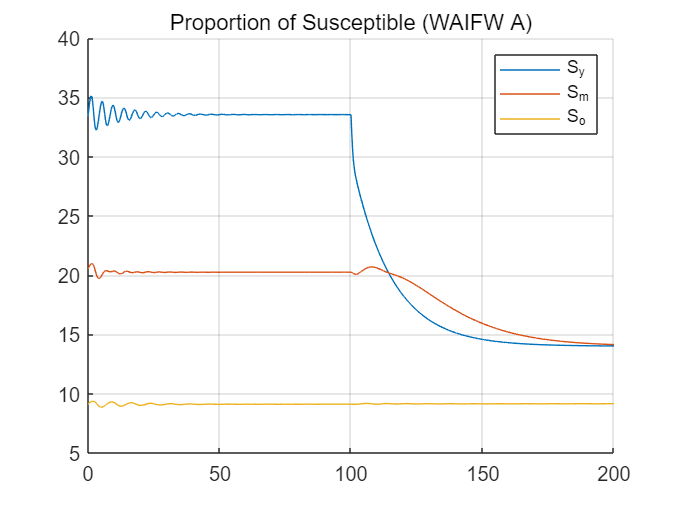

%proportion of individuals who are susceptible
prop_Sy_A = 100*y_A_vac(:,1)./N_y; 
prop_Sm_A = 100*y_A_vac(:,5)./N_m; 
prop_So_A = 100*y_A_vac(:,9)./N_o;

prop_Sy_B = 100*y_B_vac(:,1)./N_y; 
prop_Sm_B = 100*y_B_vac(:,5)./N_m; 
prop_So_B = 100*y_B_vac(:,9)./N_o;

figure(1)
hold on
plot(t_stamp./365,prop_Sy_A)
plot(t_stamp./365,prop_Sm_A)
plot(t_stamp./365,prop_So_A)
grid on;
subtitle('Proportion of Susceptible (WAIFW A)')
legend('S_y','S_m','S_o')
hold off

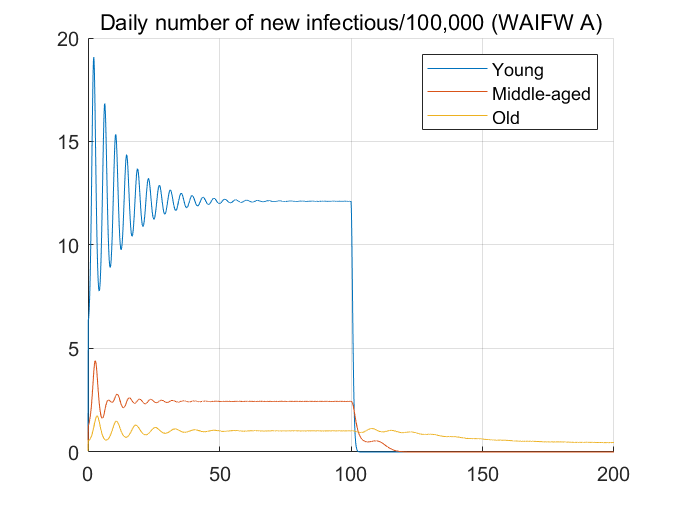

% the daily number of new infections per 100,000
NewI_A_y_vac = (100000/N_y)*f*(y_A_vac(1:end-1,2)+y_A_vac(2:end,2))/2;
NewI_A_m_vac = (100000/N_m)*f*(y_A_vac(1:end-1,6)+y_A_vac(2:end,6))/2;
NewI_A_o_vac = (100000/N_o)*f*(y_A_vac(1:end-1,10)+y_A_vac(2:end,10))/2;

figure(2)
hold on
tt_stamp = t_stamp(1:end-1);
plot(tt_stamp./365,NewI_A_y_vac)
plot(tt_stamp./365,NewI_A_m_vac)
plot(tt_stamp./365,NewI_A_o_vac)
grid on;
subtitle('Daily number of new infectious/100,000 (WAIFW A)')
legend('Young','Middle-aged','Old')
hold off

Proportion of susceptible decreases dramatically in young age group and gradually decreases in middle age group. There was no change in old age group.

New infection per 100,000 in young age group and middle age group went to 0, but old age group had slight decrease and converged to 0.5 from 1.

#### 3. What happens to the age-specific proportion of individuals who are susceptible and the daily number of new infections per 100,000 if you introduce 86% effective vaccination coverage into a population mixing according to WAIFW B? Why?

figure(3)

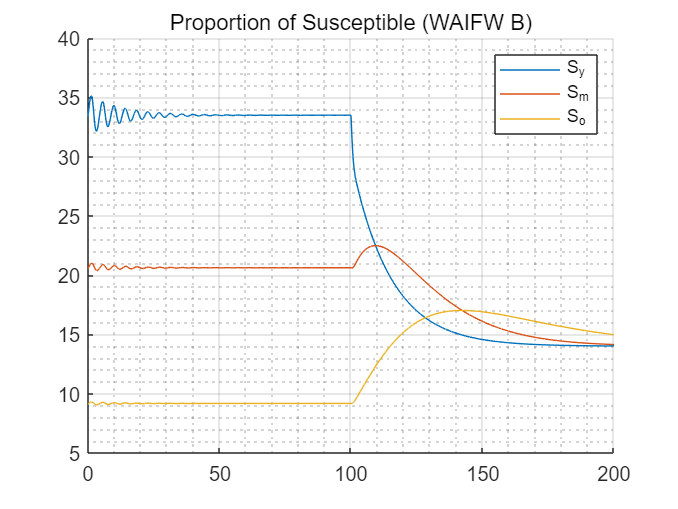

hold on
plot(t_stamp./365,prop_Sy_B)
plot(t_stamp./365,prop_Sm_B)
plot(t_stamp./365,prop_So_B)
grid on; grid minor;
subtitle('Proportion of Susceptible (WAIFW B)')
legend('S_y','S_m','S_o')
hold off

Proportion of susceptible decreases dramatically in young age group and there was gradual decreased followed by slight increase in middle age group. There was gradual increase in old age group for 40 years

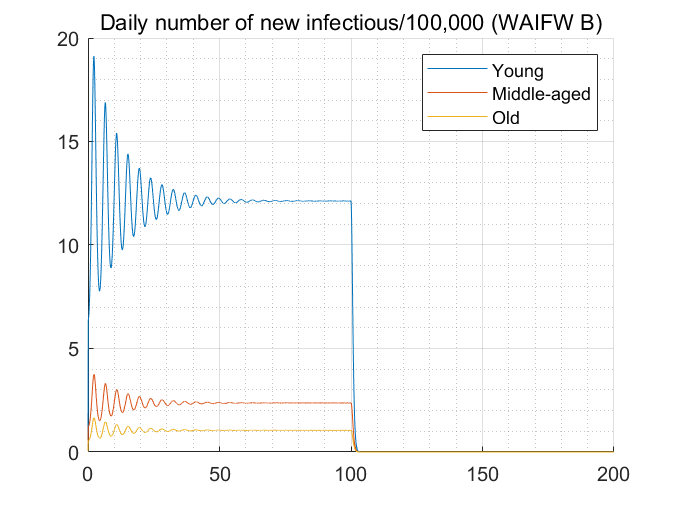

NewI_B_y_vac = (100000/N_y)*f*(y_B_vac(1:end-1,2)+y_B_vac(2:end,2))/2;
NewI_B_m_vac = (100000/N_m)*f*(y_B_vac(1:end-1,6)+y_B_vac(2:end,6))/2;
NewI_B_o_vac = (100000/N_o)*f*(y_B_vac(1:end-1,10)+y_B_vac(2:end,10))/2;

figure(4)
hold on
tt_stamp = t_stamp(1:end-1);
plot(tt_stamp./365,NewI_B_y_vac)
plot(tt_stamp./365,NewI_B_m_vac)
plot(tt_stamp./365,NewI_B_o_vac)
grid on; grid minor;
subtitle('Daily number of new infectious/100,000 (WAIFW B)')
legend('Young','Middle-aged','Old')
hold off

Daily number of new infections decreased to zero for all age groups.

#### 4. As you shall see in the next practical, the R0 for populations with mixing patterns described by WAIFW A and B are about 10.9 and 3.6, respectively. Use these values of the basic reproduction number to calculate the critical levels of vaccination coverage for these populations. Is this consistent with your answer to the previous question? What do you conclude from this exercise?

R0_A = 10.9;
R0_B = 3.6;
fprintf('critical levels of vaccination coverage\nWAIFW A : %.1f%% \nWAIFW B : %.1f%%',(1-1/R0_A)*100,(1-1/R0_B)*100)

critical levels of vaccination coverage
WAIFW A : 90.8% 
WAIFW B : 72.2%

WAIFW A: 1-1/10.9 = 90.8%

WAIFW B: 1-1/3.6 = 72.2%

86% coverage is between 72.2% and 90.8%. With WAIFW A, coverage of 86% is not enough for herd immunity, but for WAIFW B, 86% coverage is enough for herd immunity leading to 0 new infection in long term.

Result of control can be different in different assumption used in WAIFW matrix. 

function dydt = ODEftn(WAIFW,c,y,t)

N0 = 60000;
b = 1/60/365;
d = 1/30/365;
a_y = 1/15/365;
a_m = 1/15/365;
f = 1/10;
r = 1/11;

vac = @(t) logical(floor(t/(100*365)))*c;  % floor = []

dydt = [(1-vac(t))*N0*b-WAIFW(1,:)*[y(3);y(7);y(11)]*y(1)-a_y*y(1); ...
        WAIFW(1,:)*[y(3);y(7);y(11)]*y(1)-f*y(2)-(a_y)*y(2);...
        f*y(2)-r*y(3)-(a_y)*y(3);...
        (vac(t))*N0*b+r*y(3)-(a_y)*y(4);...
          (a_y)*y(1)-WAIFW(2,:)*[y(3);y(7);y(11)]*y(5)-(a_m)*y(5);...
          (a_y)*y(2)+WAIFW(2,:)*[y(3);y(7);y(11)]*y(5)-f*y(6)-(a_m)*y(6);...
          (a_y)*y(3)+f*y(6)-r*y(7)-(a_m)*y(7);...         
          (a_y)*y(4)+r*y(7)-(a_m)*y(8);...                 
         (a_m)*y(5)-WAIFW(3,:)*[y(3);y(7);y(11)]*y(9)-d*y(9);...
         (a_m)*y(6)+WAIFW(3,:)*[y(3);y(7);y(11)]*y(9)-f*y(10)-d*y(10);...
         (a_m)*y(7)+f*y(10)-r*y(11)-d*y(11);...
         (a_m)*y(8)+r*y(11)-d*y(12)];

end